# PubChem_SDQ_Bibliometrics

Count references in PubChem associated with a CID (e.g., from PubMed, Patent, Springer Nature, Thieme, and Wiley Collections)

% Vincent F. Scalfani, Serena C. Ralph, Ali Al Alshaikh, and Jason E. Bara
% The University of Alabama
% Tested with MATLAB R2020a, running Ubuntu 18.04 on March 30, 2020.
% PubChem SDQ is used internally by PubChem webpages and is still being rapidly developed.

## Define the PubChem API and SDQ agent base URL

% PubChem API
api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/';
% PubChem SDQ agent
sdq = 'https://pubchem.ncbi.nlm.nih.gov/sdq/sdqagent.cgi?outfmt=json&query=';

% set a longer web options timeout
% this prevents a MATLAB timeout if the server is slow to respond.
options_api = weboptions('Timeout', 30);
options_sdq = weboptions('Timeout', 60,'ContentType','json');

% Retrieve and display a PNG image of 1-Butyl-3-methyl-imidazolium; CID 2734162
CID_SS_query = '2734162';

*Replace the above CID value (CID_SS_query) with a different CID number to customize.*

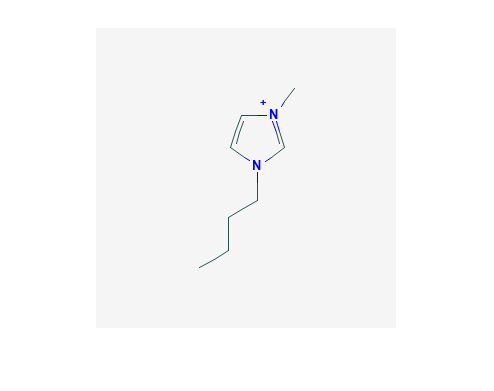

CID_url = [api 'cid/' CID_SS_query '/PNG'];
[CID_img,map] = imread(CID_url);
imshow(CID_img,map)

## Perform a Similarity Search

% Search for chemical structures by Similarity Search (SS),
% (2D Tanimoto threshold 95% to 1-Butyl-3-methyl-imidazolium; CID 2734162)
api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/';
SS_url = [api 'fastsimilarity_2d/cid/' CID_SS_query '/cids/JSON?Threshold=95'];
SS_CIDs = webread(SS_url,options_api);
SS_CIDs = num2cell(SS_CIDs.IdentifierList.CID)

SS_CIDs = 249×1 cell array
    {[12971008]}
    {[  304622]}
    {[   61347]}
    {[11448496]}
    {[11424151]}
    {[11171745]}
    {[ 2734161]}
    {[  118785]}
    {[ 2734236]}
    {[ 2734162]}
    {[  529334]}
    {[11788435]}
    {[11245926]}
    {[11160028]}
    {[ 5245884]}
    {[ 2734168]}


*In the above SS_url value, you can adjust to the desired Tanimoto threshold (e.g., 90)*

% set a CID limit to 25 max
number_SS_CIDs = length(SS_CIDs)

number_SS_CIDs = 249

*A limit of 25 was added as an initial testing safety for time consideration. This limit can be increased.*

if number_SS_CIDs > 25
   SS_CIDs = SS_CIDs(1:25)      
else
    disp('Number of SS_CIDs not changed')    
end

SS_CIDs = 25×1 cell array
    {[12971008]}
    {[  304622]}
    {[   61347]}
    {[11448496]}
    {[11424151]}
    {[11171745]}
    {[ 2734161]}
    {[  118785]}
    {[ 2734236]}
    {[ 2734162]}
    {[  529334]}
    {[11788435]}
    {[11245926]}
    {[11160028]}
    {[ 5245884]}
    {[ 2734168]}


## Retrieve Isomeric SMILES for CIDs, Number of Substances, and Literature

% setup a for loop that processes each CID one-by-one.

for j = 1:length(SS_CIDs)
    CID = SS_CIDs{j};
    
    % define api call
    api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/';
    
    % define api call for isomeric SMILES
    CID_IsoSMILES_url = [api 'cid/' num2str(CID) '/property/IsomericSMILES/TXT'];
    
    % retrieve isomeric SMILES
    try
        CID_IsoSMILES = webread(CID_IsoSMILES_url,options_api);     
    catch ME  
        CID_IsoSMILES = 'not found'
    end
        n = 0.5;
        pause(n)
            
    % add isomeric SMILES data to SS_CIDs data array
    % j increases by 1 on each iteration, so the first CID Isomeric SMILES
    % gets added to {1,2}, the second to {2,2}, third to {3,2}, etc.
        SS_CIDs{j,2} = CID_IsoSMILES;
    
    % define sdq call to retrieve count data
    sdq = 'https://pubchem.ncbi.nlm.nih.gov/sdq/sdqagent.cgi?outfmt=json&query=';
    litCountQ_url = [sdq '{"hide":"*","collection":"*","where":{"ands":{"cid":"' num2str(CID) '"}}}'];
    
    try
        litCountQ = webread(litCountQ_url, options_sdq);
    catch ME
        litCountQ = 'not found'
    end
        n = 1;
        pause(n)
        
    % add selected collection count data to SS_CIDs data array
    
    % here the column index values on the left (e.g., {j,3})
    % represent where the data will be stored (column 3), and the values
    % on the right (e.g., litCountQ.SDQOutputSet{2,1}), is an index value (2),
    % to retrieve the substance count data from the litCountQ.SDQOutputSet 
    % structure array.
        
        % substance
        SS_CIDs{j,3} = litCountQ.SDQOutputSet{2,1}.totalCount;
        % add the associated collection row value as a manual validation check
        SS_CIDs{j,4} = litCountQ.SDQOutputSet{2,1}.collection;  
        
        % patent
        SS_CIDs{j,5} = litCountQ.SDQOutputSet{4,1}.totalCount;
        SS_CIDs{j,6} = litCountQ.SDQOutputSet{4,1}.collection; 
        
        % pubmed
        SS_CIDs{j,7} = litCountQ.SDQOutputSet{7,1}.totalCount;
        SS_CIDs{j,8} = litCountQ.SDQOutputSet{7,1}.collection;
              
        % thiemechemistry
        SS_CIDs{j,9} = litCountQ.SDQOutputSet{13,1}.totalCount;
        SS_CIDs{j,10} = litCountQ.SDQOutputSet{13,1}.collection;
        
        % springernature
        SS_CIDs{j,11} = litCountQ.SDQOutputSet{15,1}.totalCount;
        SS_CIDs{j,12} = litCountQ.SDQOutputSet{15,1}.collection;
        
        % wiley
        SS_CIDs{j,13} = litCountQ.SDQOutputSet{14,1}.totalCount;
        SS_CIDs{j,14} = litCountQ.SDQOutputSet{14,1}.collection;
                        
end

*For adding custom bibliometric data counts:*

% display all available collections
collections = cell(1,length(litCountQ.SDQOutputSet)); % preallocate
for k = 1:length(litCountQ.SDQOutputSet)
    collections{k} = litCountQ.SDQOutputSet{k,1}.collection;
end
collections = collections'

collections = 33×1 cell array
    {'compound'         }
    {'substance'        }
    {'assay'            }
    {'patent'           }
    {'pathway'          }
    {'disease'          }
    {'pubmed'           }
    {'targetprotein'    }
    {'targetgene'       }
    {'targettaxonomy'   }
    {'classification'   }
    {'literature'       }
    {'thiemechemistry'  }
    {'wiley'            }
    {'springernature'   }
    {'hmdb'             }
    {'epapest'          }
    {'clinicaltrials'   }
    {'drugbank'         }
    {'gtopdb'           }
    {'geneinteractions' }
    {'probereports'     }
    {'niosh'            }
    {'chembldrugtargets'}
    {'dgidb'            }
    {'pdb'              }
    {'fdaorangebook'    }
    {'chemidplus'       }
    {'clinicaltrials_eu'}
    {'clinicaltrials_jp'}


- *Determine the collection you are interested in (e.g., 'clinicaltrials') from the litCountQ.SDQOutputSet structure*

- *Then, record the row number the collection appears in (18 for 'clinicaltrials')*

- *Next, use this number to index into the litCountQ.SDQOutputSet *

- *For example, litCountQ.SDQOutputSet{18,1}.totalCount*

- *Add the new bibliometric data count into the for loop above. *

## Validate Extracted Counts and Fields

% convert cell array to string and remove leading and trailing white space
SS_CIDs_string = strtrim(string(SS_CIDs));

% convert to table and verify expected counts match extracted collection
% e.g., in the patent_lab column all rows should be 'patent'
SSq_bibtable_validate = array2table(SS_CIDs_string, 'VariableNames',{'CID','Isomeric_SMILES','num_substances',...
    'substances_lab','num_patent','patent_lab','num_pubmed','pubmed_lab','num_thiemechemistry',...
    'thiemechemistry_lab','num_springernature','springernature_lab','num_wiley','wiley_lab'})

SSq_bibtable_validate = 25×14 table
       CID                  Isomeric_SMILES              num_substances    substances_lab    num_patent    patent_lab    num_pubmed    pubmed_lab    num_thiemechemistry    thiemechemistry_lab    num_springernature    springernature_lab    num_wiley    wiley_lab
    __________    ___________________________________    ______________    ______________    __________    __________    __________    __________    ___________________    ___________________    __________________    __________________    _________

## Compile Bibliometric Data into a Table

% select only the numerical count data to export
SSq_bibtable = SSq_bibtable_validate(:, {'Isomeric_SMILES' 'CID' 'num_substances' 'num_patent' 'num_pubmed'...
    'num_thiemechemistry' 'num_springernature' 'num_wiley'})

SSq_bibtable = 25×8 table
              Isomeric_SMILES                 CID        num_substances    num_patent    num_pubmed    num_thiemechemistry    num_springernature    num_wiley
    ___________________________________    __________    ______________    __________    __________    ___________________    __________________    _________

    "CCCN1C=C[N+](=C1)C.[I-]"              "12971008"        "69"            "104"         "0"                "0"                   "142"             "5"    
    "CCCCN1C=CN=C1C"                       "304622"          "51"            "126"         "7"                "0"                   "7"               "0"    
    "CCCCN1C=CN=C1"                        "61347"           "103"   

% export data as tabbed text file
% prompt user to select folder for data export
save_folder = uigetdir;

% change directory to selected folder
cd(save_folder)
writetable(SSq_bibtable,'MATLAB_SDQ_Bibliometrics_results.txt','Delimiter','tab')